#### **1.*** A state space system is described by the system matrices*

clear;

A = [12.5314, -91.36   , 28.7129, 59.9628; 
     21.316 , -115.6631, 37.5584, 75.0519; 
     13.967 , -53.5817 , 15.4161, 33.4391; 
     20.5222, -123.3107, 42.267 , 79.7156];
 
B = [1.7649, 1.7649; 
     2.8318, 2.8318; 
     2.2353, 2.2353; 
     2.7294, 2.7294];
 
C = [-0.46166, -4.4635, 1.9151, 3.7274;
      1.0853 , -12.82 , 4.5753, 8.3759];
  
D = [0, 0; 
     0, 0];

**a)*** If the system begins in a state *$\mathit{\mathbf{x}}\left(0\right)={\left\lbrack 1\;1\;1\;2\right\rbrack }^T$*, use matlab's *`lsim `*command to plot the response of the system in the time interval *$t\in \left\lbrack 0,10\right\rbrack \;s$*. You should plot the evolution of the system state *$\left(\mathit{\mathbf{x}}\right)$* and its output*$\left(\mathit{\mathbf{y}}\right)$*as a functions of time.*

*Hint: BY default, Matlab will plot the system response for you when you use *`lsim`*, but make sure that you can extract the required signal from *`lsim`* so that you can do other things with them (including plotting them yourself). We will need this later.*

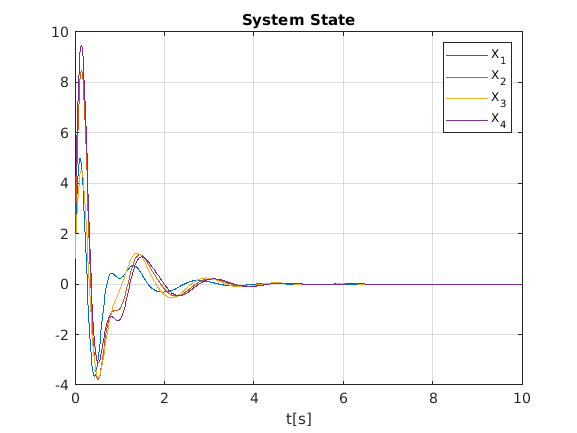

sys = ss(A,B,C,D);                  %create system
x0 = [1; 1; 1; 2];                  %intial state
t = 0:0.01:10;                      %time vector
u = zeros(length(t),2);             %inputs for all t, 2 wide
[Y,T,X] = lsim(sys,u,t,x0);         %extract outputs, t vect, and states

figure();
plot(T,X);
title("System State");
legend("X_1","X_2","X_3","X_4");
xlabel('t[s]')
grid on;

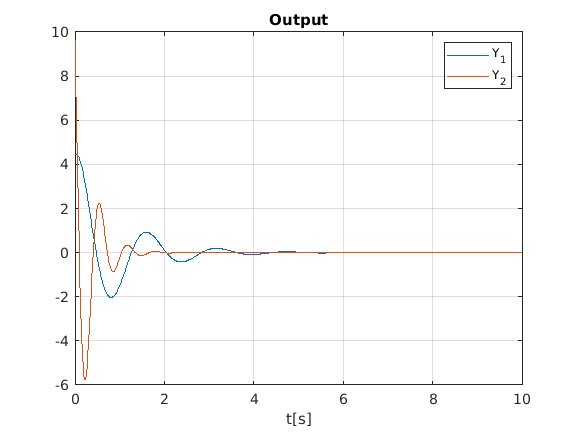

figure();
plot(T,Y);
title("Output");
legend("Y_1","Y_2");
xlabel('t[s]')
grid on;

**b****)*** Replicate the results from above using the matrix exponential to evolve the state, rather than *`lsim`*.*

Xe = [];                    %State history 
Ye = [];                    %Output history 
for t_ = t                  %reuse previous t vector
    xe = expm(A*t_)*x0;     %compute phi*x_0
    ye = C*xe + D*[0; 0];   %output
    
    %append to history
    Xe = [Xe; xe'];
    Ye = [Ye; ye'];
end

figure();
plot(t',Xe);
title("System State");
legend("X_1","X_2","X_3","X_4");
xlabel('t[s]')
grid on;

figure();
plot(t',Ye);
title("Output");
legend("Y_1","Y_2");
xlabel('t[s]')
grid on;

**c)*** Use *`lsim` *to plot the response of the system to the input signal *$\mathit{\mathbf{u}}={\left\lbrack u_1 \;\;\;\;u_2 \right\rbrack }^T$*with:*


$$\begin{array}{l}
u_1 =u\left(t-1\right)\\
u_2 =2u\left(t-5\right)
\end{array}$$


*for *$u$* the (Heaviside) unit step function.*

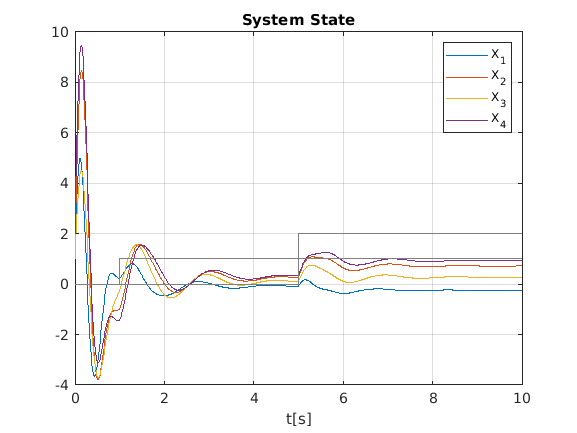

u_ = zeros(length(t),2);         %generate empty input
u_(t>=1,1) = 1;                  %piecewise steps at t=1 and t=5
u_(t>=5,2) = 2;

[Y_,T_,X_] = lsim(sys,u_,t,x0);

figure();
plot(T_,X_);
hold on
plot(t,u_,'Color',[0.5,0.5,0.5]);
hold off
title("System State");
legend("X_1","X_2","X_3","X_4");
xlabel('t[s]')
grid on;

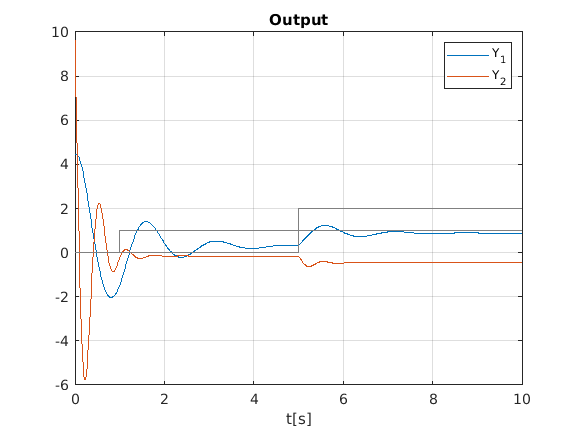

figure();
plot(T_,Y_);
hold on
plot(t,u_,'Color',[0.5,0.5,0.5]);
hold off
title("Output");
legend("Y_1","Y_2");
xlabel('t[s]')
grid on;

**d)*** Use *`c2d` *to discretize the system with an appropriate sampling frequency and use *`lsim` *to plot the response of the discrete time system.*

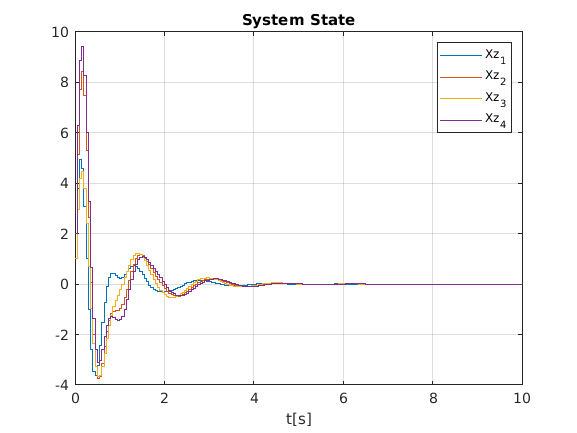

ts=0.05;                                %sampling time
zyz = c2d(sys,ts);                      %discrete system
tz = 0:ts:10;                           %match t vector and input
uz = zeros(length(tz),2);

[Yz,Tz,Xz] = lsim(zyz,uz,tz,x0);

figure();
stairs(Tz,Xz);
title("System State");
legend("Xz_1","Xz_2","Xz_3","Xz_4");
xlabel('t[s]')
grid on;

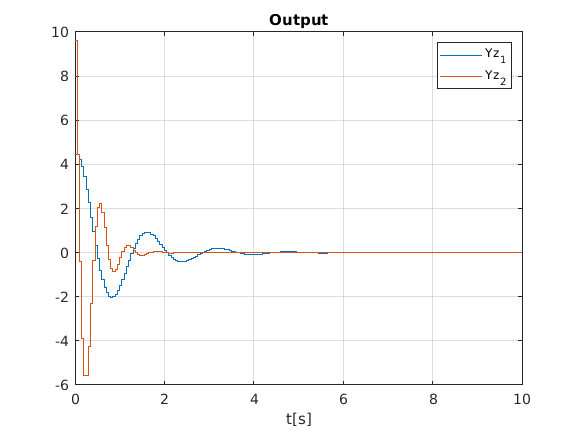

figure();
stairs(Tz,Yz);
title("Output");
legend("Yz_1","Yz_2");
xlabel('t[s]')
grid on;

**e)*** Vary the sampling period and describe the effect on the output.*

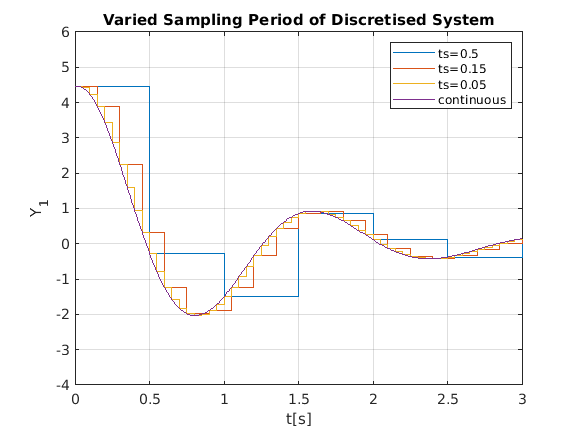

figure();
for ts = [0.5 0.15 0.05]                %varied ts's 
    zyz = c2d(sys,ts);
    tz = 0:ts:10;
    uz = zeros(length(tz),2);

    [Yz,Tz,Xz] = lsim(zyz,uz,tz,x0);
    stairs(tz, Yz(:,1))
    hold on
end
plot(T,Y(:,1))                          %plot the orignial system
title('Varied Sampling Period of Discretised System')
legend("ts=0.5","ts=0.15", "ts=0.05", "continuous");
xlim([0.00 3])
ylim([-4 6])
xlabel('t[s]')
ylabel('Y_1')
grid on
hold off

Varying the sampling time most noticablly affects the resolution of the computed signals. Hense showing to accuratly reporesent a given system an appropriate `ts` must be chosen to prevent aliasing of the given states/outputs, though any given point is still accurate.

**f)** *Find the time response for the discrete time system of there is no input and initial conditions of*$\mathit{\mathbf{x}}={\left\lbrack 1\;1\;1\;2\right\rbrack }^T$*. Determine this response using powers of*$\mathit{\mathbf{A}}$*directly (ie, do not use *`lsim`*).*

Ad = expm(ts*A);                    %compute discrete A matrix

Xzp = [];
Yzp = [];

for tz_ = tz
    xzp = real((Ad^(tz_/ts))*x0);   %compute next state and scale be sampling time 
    yzp = C*xzp;
    
    Xzp = [Xzp; xzp'];
    Yzp = [Yzp; yzp'];
end

figure();
stairs(tz,Xzp);
title("System State");
legend("Xz_1","Xz_2","Xz_3","Xz_4");
xlabel('t[s]')
grid on;

figure();
stairs(tz,Yzp);
title("Output");
legend("Yz_1","Yz_2");
xlabel('t[s]')
grid on;

#### 2. The phase-shift oscillator circuit shown in figure 1 can be described by the coupled differential equations


$$\begin{array}{l}
{\dot{v} }_a =-\frac{2v_a }{\textrm{RC}}+\frac{v_b }{\textrm{RC}}-\frac{R_2 }{R_1 }\frac{v_c }{\textrm{RC}}\\
{\dot{v} }_b =\frac{v_a }{\textrm{RC}}-\frac{2v_b }{\textrm{RC}}+\frac{v_c }{\textrm{RC}}\\
{\dot{v} }_c =\frac{v_b }{\textrm{RC}}-\frac{v_c }{\textrm{RC}}-\frac{v_c }{R_1 C}
\end{array}$$


#### where $v_a$, $v_b$ and $v_c$ are the voltages after the three successive $\textrm{RC}$ stages.

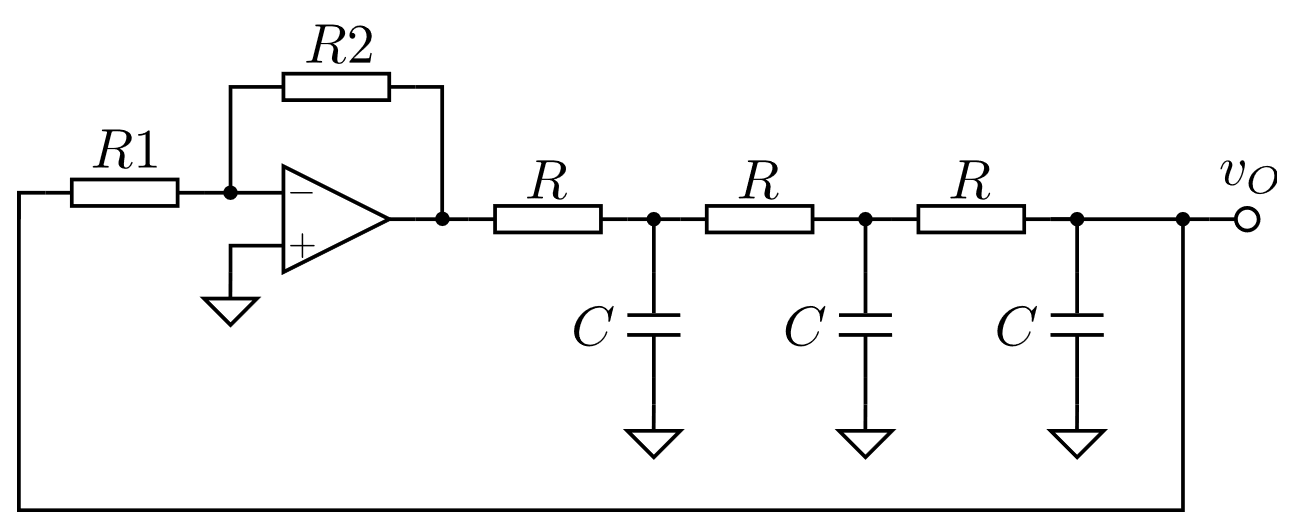

Figure 1: An unbuffered phase-shift oscillator

**a) ***Write a state space representation for the system.*


$$\left\lbrack \begin{array}{c}
{\dot{v} }_a \\
{\dot{v} }_b \\
{\dot{v} }_c 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\frac{2}{\textrm{RC}} & \frac{1}{\textrm{RC}} & -\frac{R_2 }{R_1 }\frac{1}{\textrm{RC}}\\
\frac{1}{\textrm{RC}} & -\frac{2}{\textrm{RC}} & \frac{1}{\textrm{RC}}\\
0 & \frac{1}{\textrm{RC}} & -\frac{1}{\textrm{RC}}-\frac{1}{R_1 C}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_a \\
v_b \\
v_c 
\end{array}\right\rbrack$$



$$v_o =\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_a \\
v_b \\
v_c 
\end{array}\right\rbrack$$



$$A=$$

$$\left\lbrack \begin{array}{ccc}
-\frac{2}{\textrm{RC}} & \frac{1}{\textrm{RC}} & -\frac{R_2 }{R_1 }\frac{1}{\textrm{RC}}\\
\frac{1}{\textrm{RC}} & -\frac{2}{\textrm{RC}} & \frac{1}{\textrm{RC}}\\
0 & \frac{1}{\textrm{RC}} & -\frac{1}{\textrm{RC}}-\frac{1}{R_1 C}
\end{array}\right\rbrack ,\;C=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack$$


**b) ***The ratio *$\frac{\textrm{R2}}{\textrm{R1}}\approx 30$* matters if the oscillator is to maintain sustained oscillations.*

*Find the value for this ratio that correctly induces oscillation, making sure that you explain your process.*

*Hint: You could solve this problem analytically, but don’t!*

*Hint: You should choose some convenient values for R and C, given that the nominal oscillation angular frequency is *$\omega_0 =\frac{1}{\sqrt{6}\textrm{RC}}$ .

**Ans.** The eigenvalues of the $A$ matrix correspond to the poles of the system. So to find the point of sustained oscilations, we are looking for purely imagginary poles, e.g. $0\pm 1i$.

To find this, R, R1, C were set and R2 swept to find the purely imaginary dominatn poles.

clear;

r=1000;
r1=r;
c=1e-3;

C=[0, 0, 1];
B=[];
D=[];

res=[];
for r2 = 1000:10:100000     %sweep R2 values
    A=[-(2/(r*c)), 1/(r*c), -(r2/r1)*(1/(r*c));
        1/(r*c)  ,-2/(r*c),  1/(r*c)          ;
        0        ,1/(r*c), -(1/(r*c))-(1/(r1*c))];
    res = [res; [r2,eig(A)']];
    if real(res(end,3)) == 0 %check zero real
        r2
        ratio = r2/r1
        eig(A)
    end
end

r2 = 56000

ratio = 56

ans =   -6.0000 + 0.0000i
   0.0000 + 3.1623i
   0.0000 - 3.1623i


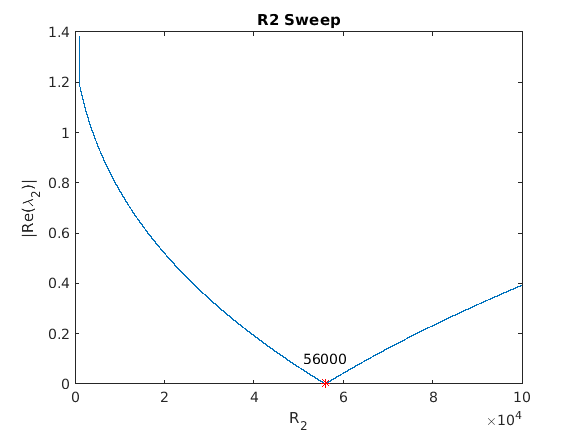

r2 = ratio*r1;
figure();
pos_0 = find(real(res(:,3))==0);
plot(real(res(:,1)), abs(real(res(:,3))),'*-','MarkerEdgeColor','red','MarkerIndices', pos_0)
text(real(res(pos_0,1))-5000, abs(real(res(pos_0,3))-0.1),num2str(r2))
xlabel('R_2')
ylabel('|Re(\lambda_2)|')
title('R2 Sweep')

Theis gives a R2/R1 ratio of 56 for R=R1=1000

**c) ***Determine the oscillation frequency of the circuit using the state space model.*


 A=[-(2/(r*c)) , 1/(r*c), -(r2/r1)*(1/(r*c));
        1/(r*c),-2/(r*c),   1/(r*c)         ;
        0      , 1/(r*c), -(1/(r*c))-(1/(r1*c))];
poles = eig(A)

poles =   -6.0000 + 0.0000i
   0.0000 + 3.1623i
   0.0000 - 3.1623i



w = imag(poles(2)) %rad/s

w = 3.1623


f = w/(2*pi) %Hz

f = 0.5033

**d) ***Simulate the operation of the oscillator to show that it works as you might expect.*

*Hint: Think about the initial conditions for the simulation.*

**Ans: **By using the the eigenvector(s) of the oscilatry pole are an inital state we can observer the sustained oscilations at the above computed frequency.

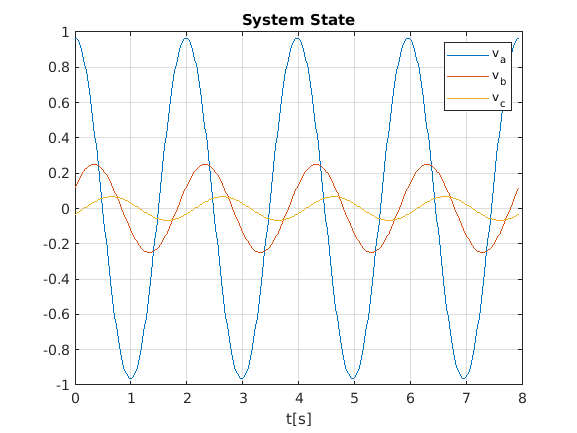

sys = ss(A,B,C,D);
[V,wc] = eig(A);
x0 = V(:,2);
t = 0:0.01/f:4/f;
[Y,T,X] = lsim(sys,[],t,x0);

figure();
plot(T,real(X));
title("System State");
legend("v_a","v_b","v_c");
xlabel('t[s]')
grid on;

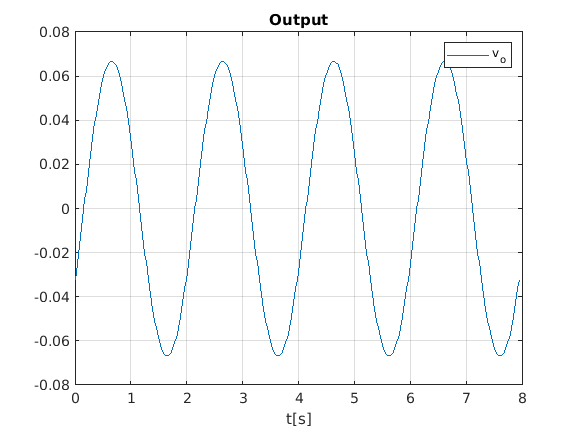

figure();
plot(T,real(Y));
title("Output");
legend("v_o");
xlabel('t[s]')
grid on;

#### *3. You need to design a simple open loop "controller" that causes a rocket to pitch *${10}^{\circ }$* clockwise by the end of the first 15 seconds of flight. The idea is nominally to let the rocket ascend for the first five seconds and then pitch over at approximately *$1^{\circ } /s$* for the remaining 10 seconds. The main rocket engine is at full burn throughout the period.*

#### *A continuous time, nonlinear model for the rocket is as described below. Simulation code for the complete nonlinear system is available on the course website.*

#### *In this question you will investigate the approximations due to linearisation of the system, as well as examining the time evolution of the system.*

Let the state vector be defined as follows:

                        $x_1 \equiv$ Rocket’s altitude (positive upwards) $\left\lbrack m\right\rbrack$

                        $x_2 \equiv$ Rocket’s vertical velocity (positive upwards) $m/s$

                        $x_3 \equiv$ Rocket’s horizontal position relative to launch site $\left\lbrack m\right\rbrack$

                        $x_4 \equiv$ Rocket’s horizontal ground speed $\left\lbrack m/s\right\rbrack$

                        $x_5 \equiv$ Rocket’s angle from vertical $\left\lbrack \circ \right\rbrack$

                        $x_6 \equiv$ Rocket’s angular velocity $\left\lbrack \circ /s\right\rbrack$

                        $x_7 \equiv$ Fuel load $\left\lbrack \textrm{kg}\right\rbrack$

and the input vector is:

                        $u_1 \equiv$ Main engine force (positive upwards) $\left\lbrack N\right\rbrack$

                        $u_2 \equiv$ Orientation thruster force (positive rotates the rocket clockwise) $\left\lbrack N\right\rbrack$

The initial state is:

                        $x\left(0\right)={\left\lbrack \begin{array}{ccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 1000
\end{array}\right\rbrack }^T$,

which is to say that before launch it is stationary at the origin, with 1000 kg of fuel on board.

The rocket’s state evolves according to the following set of nonlinear equations.


$$\left\lbrace \begin{array}{l}
{\dot{x} }_1 =x_2 \\
{\dot{x} }_2 =g-c_d x_2^2 +\frac{\cos \left(x_5 \right)}{\left(M+x_7 \right)}u_1 \\
{\dot{x} }_3 =x_4 \\
{\dot{x} }_4 =-\frac{\sin \left(x_5 \right)}{\left(M+x_7 \right)}u_1 \\
{\dot{x} }_5 =x_6 \\
{\dot{x} }_6 =\frac{k}{J+L^2 x_7 }\\
{\dot{x} }_7 =-\frac{1}{\eta }\left(u_1 +u_2 \right)
\end{array}\right.$$


where,$\left\lbrace \begin{array}{l}
g=9\ldotp 8\;\textrm{the}\;\textrm{acceleration}\;\textrm{due}\;\textrm{to}\;\textrm{gravity}\;\left\lbrack {\textrm{ms}}^{-2} \right\rbrack \\
c_d =2\times {10}^{-3} \;\textrm{is}\;\textrm{the}\;\textrm{coefficient}\;\textrm{of}\;\textrm{drag}\;\left\lbrack {\textrm{Nm}}^{-2} s^2 \right\rbrack \\
M=1000\;\textrm{is}\;\textrm{the}\;\textrm{mass}\;\textrm{of}\;\textrm{the}\;\textrm{empty}\;\textrm{rocket}\;\left\lbrack \textrm{kg}\right\rbrack \\
J=20,000\;\textrm{is}\;\textrm{the}\;\textrm{moment}\;\textrm{of}\;\textrm{inertia}\;\textrm{of}\;\textrm{empty}\;\textrm{rocket}\;\left\lbrack \textrm{kg}\;m^2 \right\rbrack \\
L=5\;\textrm{is}\;\textrm{the}\;\textrm{distance}\;\textrm{between}\;\textrm{the}\;\textrm{rocket’s}\;\textrm{centre}\;\textrm{of}\;\textrm{mass}\;\textrm{and}\;\textrm{the}\;\textrm{centre}\;\textrm{of}\;\textrm{the}\;\textrm{fuel}\;\textrm{load}\;\left\lbrack m\right\rbrack \\
\eta =1000\;\textrm{is}\;\textrm{the}\;\textrm{efficiency}\;\textrm{of}\;\textrm{the}\;\textrm{fuel}\;\left\lbrack \textrm{Ns}/\textrm{kg}\right\rbrack \\
k=6\;\textrm{is}\;\textrm{the}\;\textrm{distance}\;\textrm{between}\;\textrm{the}\;\textrm{rotation}\;\textrm{thruster}\;\textrm{and}\;\textrm{the}\;\textrm{centre}\;\textrm{of}\;\textrm{mass}\;\left\lbrack m\right\rbrack 
\end{array}\right.$

(Note that these quantities may not make physical sense; they are constructed to make an interesting exercise. In addition, the model doesn’t attempt to capture all of the nonlinear effects. As an example $L$ should most likely change as the fuel load is depleted.)

Hints:

1. The nonlinear simulation code calculates the rocket’s trajectory in time chunks of length `dt`. The control input $\mathit{\mathbf{u}}$ is calculated only once per time chunk. If you decrease `dt` the ODE solver may be more accurate, and as a side effect you can calculate $\mathit{\mathbf{u}}$ more frequently (and vice versa). This may be useful for debugging, but your final solution will be marked with `dt=1`. However, for this assignment you need not change $\mathit{\mathbf{u}}$ anyway, so there is little to be gained by changing $\textrm{dt}$.

2. The sample code includes a symbolic model `f_sym` that should be useful in finding the linear approximations of the system, but you may choose to find it by hand. To implement the linearised systems, you should find a linear model and then rewrite the simulation section of the code to use `lsim` rather than `ode45`.

**a)** **[5 marks]*** Use the nonlinear model to devise a nominal control signal *$\mathit{\mathbf{u}}$*. You should assume that *$u_1$* is a constant throughout the 15 seconds of flight, such that there is no remaining fuel after that time. You should then choose *$u_2$* to effect the required pitch-over maneouvre.*

*You don’t need to be too fussy about this; just devise something simple that you can use for comparison in the following parts of the question.*

*Hint: Your code to set *$\mathit{\mathbf{u}}$* should go in the section marked with asterisks. The simulation will not do much until you out something in this section.*

**Ans.** $\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
42000\\
1198\ldotp 75
\end{array}\right\rbrack \to \mathrm{final}\;\mathrm{angle}:10\ldotp 0000$

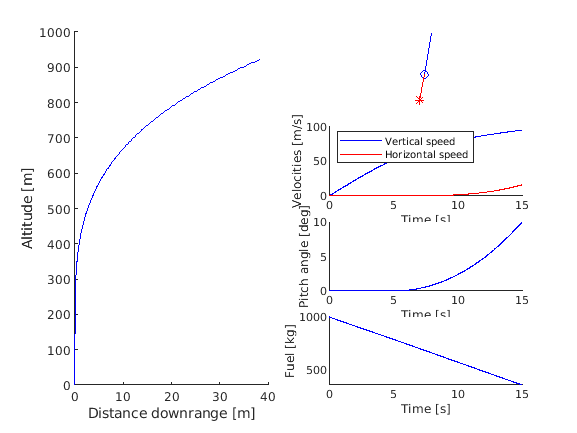

final_angle = 10.0000

clear;
constant_u1 = 42000;
final_u2 = 1198.75;
figure();
run("q3_nonlinear_sim.m");

**b) [2 marks]** *What is the maximum acceleration seen by the rocket during the launch?*

T = unique(t_store);
clean_X = unique(x_store,"rows");

v_y = clean_X(:,2);
v_x = clean_X(:,4);

a_y = diff(v_y)./diff(T);
a_x = diff(v_x)./diff(T);
a = sqrt((a_x.^2)+(a_y.^2));

[a_max, max_i] = max(a)

a_max = 11.3965

max_i = 57

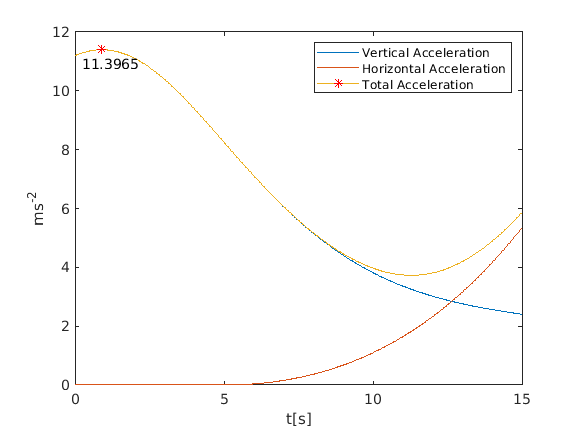


figure();
% subplot(111);
plot(T(2:end),a_y,T(2:end),a_x,T(2:end),a,'*-','MarkerEdgeColor','red','MarkerIndices', max_i);
legend({'Vertical Acceleration','Horizontal Acceleration','Total Acceleration'})
text(T(max_i-25), a(max_i)-0.5, num2str(a_max))
xlabel('t[s]')
ylabel('ms^{-2}')

Maximum Total Acceleration experienced was $11\ldotp 3965{\mathrm{ms}}^{-2}$

**c) [3 marks] ***Which state variables are important in the linearisation? That is, in which variables is the model nonlinear? Provide physical reasoning for the identified nonlinearities.*

**Ans. **$x_{\left\lbrack 2,4,6\right\rbrack }$ are related the varieous velocities of the rocket. And as seen above the rocket experieces non-constant acceleration throughout its flight, and thus cannot experial a linear velocity change. This can be seen represented in the nonlinear elements of their equations for their change. ${\dot{\;x} }_{\left\lbrack 1,3,5\right\rbrack } \;$are derived from these and are thus also non-linear.

$x_7$ is fuel and undergoes linear depletion. 

**d) [5 marks] ***Linearise the model at the position where it begins its pitch-over maneouvre *$\left(t=5\right)$* and plot the rocket’s trajectory when you apply your nominal control signal.*

DfDx = jacobian(f_sym, [x1, x2, x3, x4, x5, x6, x7])

$$DfDx = \left(\begin{array}{ccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{x_{2}}{250} & 0 & 0 & -\frac{u_{1}\,\sin\left(x_{5}\right)}{x_{7}+1000} & 0 & -\frac{u_{1}\,\cos\left(x_{5}\right)}{{\left(x_{7}+1000\right)}^{2}}\\ 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{u_{1}\,\cos\left(x_{5}\right)}{x_{7}+1000} & 0 & -\frac{u_{1}\,\sin\left(x_{5}\right)}{{\left(x_{7}+1000\right)}^{2}}\\ 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{150\,u_{2}}{{\left(25\,x_{7}+20000\right)}^{2}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

syms u1 u2
A = subs(DfDx, [x1, x2, x3, x4, x5, x6, x7, u1, u2], [clean_X(T==5,:), constant_u1, 0])

$$A = \left(\begin{array}{ccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{366631709224507}{1759218604441600} & 0 & 0 & 0 & 0 & -\frac{420}{32041}\\ 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{4200}{179} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

DfDu = jacobian(f_sym, [u1, u2])

$$DfDu = \left(\begin{array}{cc} 0 & 0\\ \frac{\cos\left(x_{5}\right)}{x_{7}+1000} & 0\\ 0 & 0\\ \frac{\sin\left(x_{5}\right)}{x_{7}+1000} & 0\\ 0 & 0\\ 0 & \frac{6}{25\,x_{7}+20000}\\ -\frac{1}{1000} & -\frac{1}{1000} \end{array}\right)$$

B = subs(DfDu, [x1, x2, x3, x4, x5, x6, x7, u1, u2], [clean_X(T==5,:), constant_u1, 0])

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{1790} & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & \frac{1}{6625}\\ -\frac{1}{1000} & -\frac{1}{1000} \end{array}\right)$$

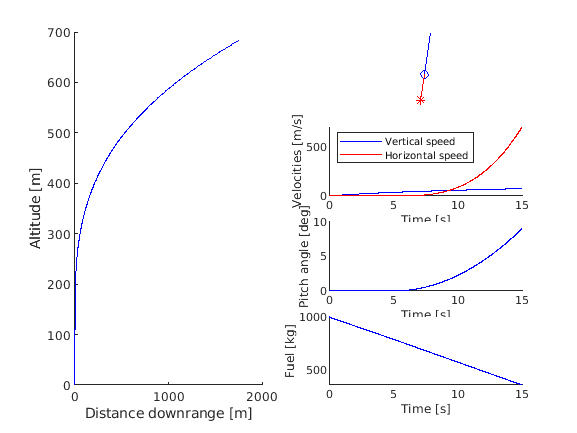

final_angle = 9.0291

A = double(A);
B = double(B);
sys = ss(A,B,[],[]);
figure();
run("q3_linearised_sim.m")

**e) [5 marks]** *Linearize the model at its final position *$\left(t=15\right)$* and plot the rocket trajectory when you apply your nominal control signal.*

DfDx = jacobian(f_sym, [x1, x2, x3, x4, x5, x6, x7])

$$DfDx = \left(\begin{array}{ccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{x_{2}}{250} & 0 & 0 & -\frac{u_{1}\,\sin\left(x_{5}\right)}{x_{7}+1000} & 0 & -\frac{u_{1}\,\cos\left(x_{5}\right)}{{\left(x_{7}+1000\right)}^{2}}\\ 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{u_{1}\,\cos\left(x_{5}\right)}{x_{7}+1000} & 0 & -\frac{u_{1}\,\sin\left(x_{5}\right)}{{\left(x_{7}+1000\right)}^{2}}\\ 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{150\,u_{2}}{{\left(25\,x_{7}+20000\right)}^{2}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

syms u1 u2
A = subs(DfDx, [x1, x2, x3, x4, x5, x6, x7, u1, u2], [clean_X(T==15,:), constant_u1, 0])

$$A = \left(\begin{array}{ccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{3361532086662463}{8796093022208000} & 0 & 0 & -\frac{3360000\,\sin\left(\frac{703690922058203}{70368744177664}\right)}{108641} & 0 & -\frac{268800000\,\cos\left(\frac{703690922058203}{70368744177664}\right)}{11802866881}\\ 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{3360000\,\cos\left(\frac{703690922058203}{70368744177664}\right)}{108641} & 0 & -\frac{268800000\,\sin\left(\frac{703690922058203}{70368744177664}\right)}{11802866881}\\ 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

DfDu = jacobian(f_sym, [u1, u2])

$$DfDu = \left(\begin{array}{cc} 0 & 0\\ \frac{\cos\left(x_{5}\right)}{x_{7}+1000} & 0\\ 0 & 0\\ \frac{\sin\left(x_{5}\right)}{x_{7}+1000} & 0\\ 0 & 0\\ 0 & \frac{6}{25\,x_{7}+20000}\\ -\frac{1}{1000} & -\frac{1}{1000} \end{array}\right)$$

B = subs(DfDu, [x1, x2, x3, x4, x5, x6, x7, u1, u2], [clean_X(T==15,:), constant_u1, 0])

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{80\,\cos\left(\frac{703690922058203}{70368744177664}\right)}{108641} & 0\\ 0 & 0\\ \frac{80\,\sin\left(\frac{703690922058203}{70368744177664}\right)}{108641} & 0\\ 0 & 0\\ 0 & \frac{96}{463205}\\ -\frac{1}{1000} & -\frac{1}{1000} \end{array}\right)$$

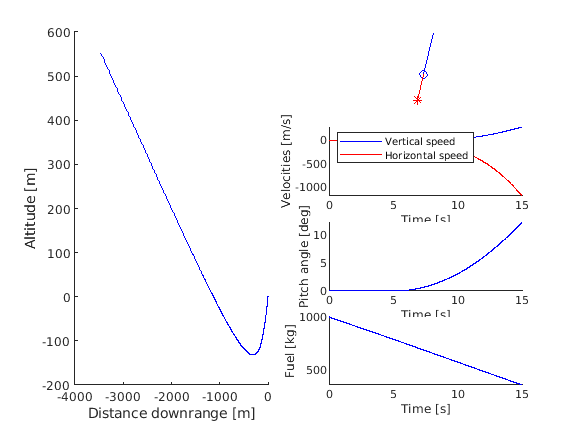

final_angle = 12.3973

A = double(A);
B = double(B);
sys = ss(A,B,[],[]);
figure();
run("q3_linearised_sim.m")

**f) [5 marks] ***Discuss what you have found from the linearisation, including the differences (if any) between them. What linearisation would you use in a practical implementation of this system?*

**Ans. **